clear;clc;


## power curve

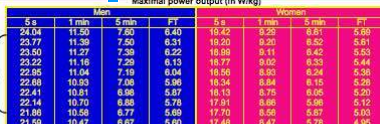

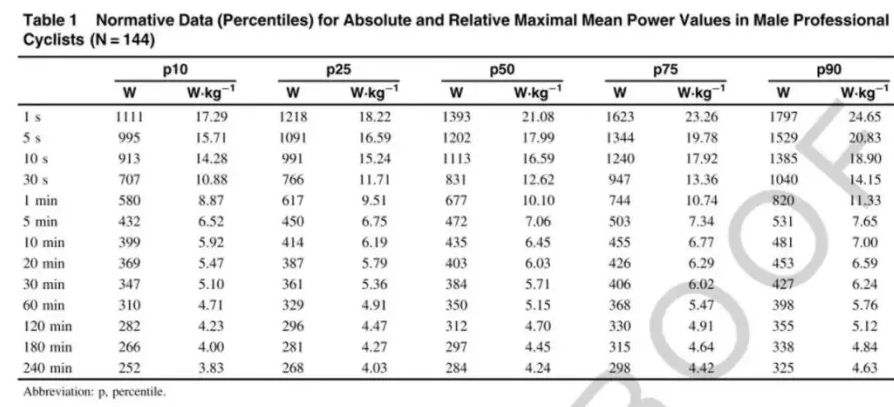

[23.26 19.78 17.92 13.36 10.74 7.34 6.77 6.29 6.02 5.47 4.91 4.64 4.42];

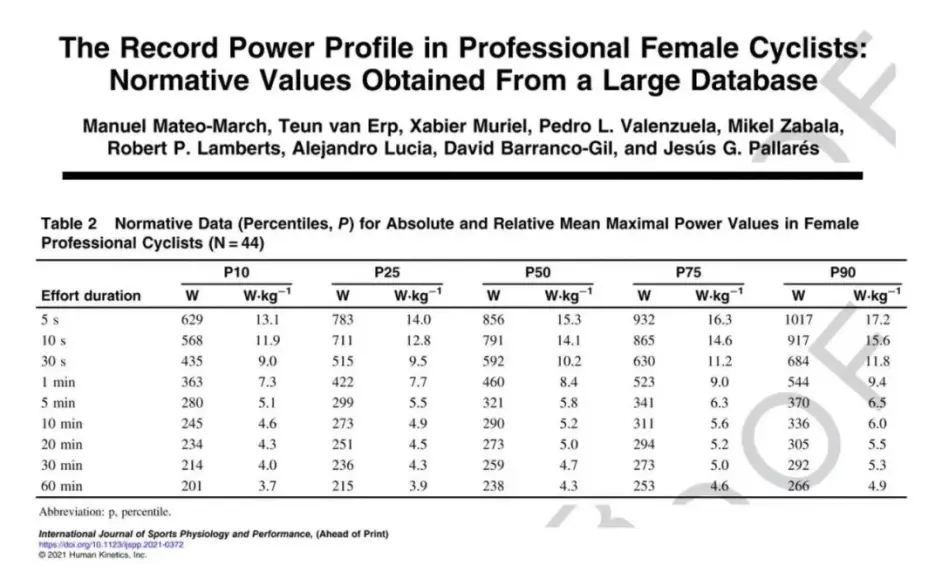

mmt.z1=[1 5 10 30 60 300 600 1200 1800 3600 7200 10800 14400];
Wpm.z1=[24.65 20.84 18.90 14.15 11.33 7.65 7.00 6.59 6.24 5.76 5.12 4.84 4.63];
% maximum 1740
mmt.z2=[5 10 30 60 300 600 1200 1800 3600];
Wpm.z2=[17.2 15.6 11.8 9.4 6.5 6.0 5.5 5.3 4.9];
wei.z1=73;
wei.z2=0.95*wei.z1;
gp.z1=Wpm.z1*wei.z1;
gp.z2=Wpm.z2*wei.z2;
n = 9 ;
[p.z1]=polyfit(mmt.z1,gp.z1,n);

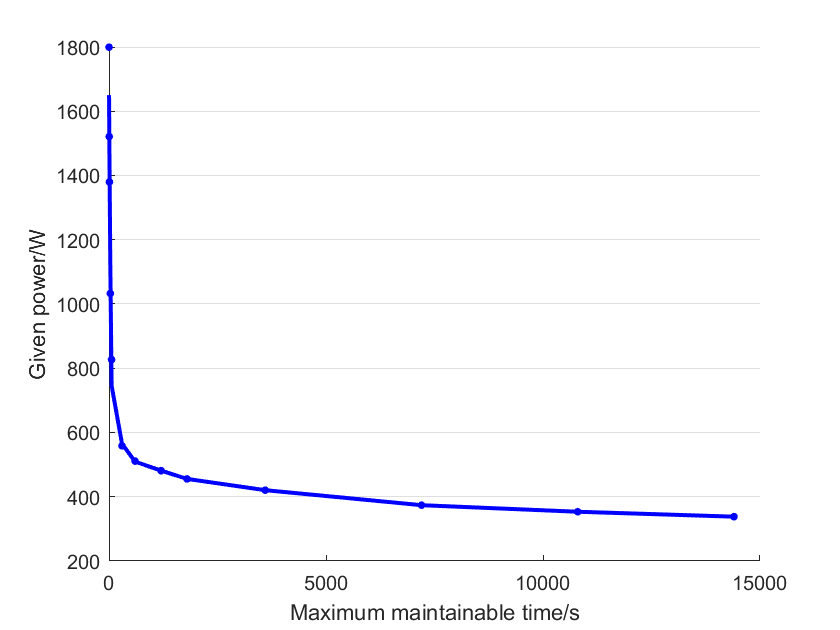

y1=polyval(p.z1,mmt.z1);

figure;hold on
plot(mmt.z1,y1,'b','LineWidth',2)
scatter(mmt.z1,gp.z1,15,'b','filled');
xlabel('Maximum maintainable time/s');ylabel('Given power/W')
set(gca,'ygrid','on')% 显示y轴网格线


figure
[p.z2]=polyfit(mmt.z2,gp.z2,n);

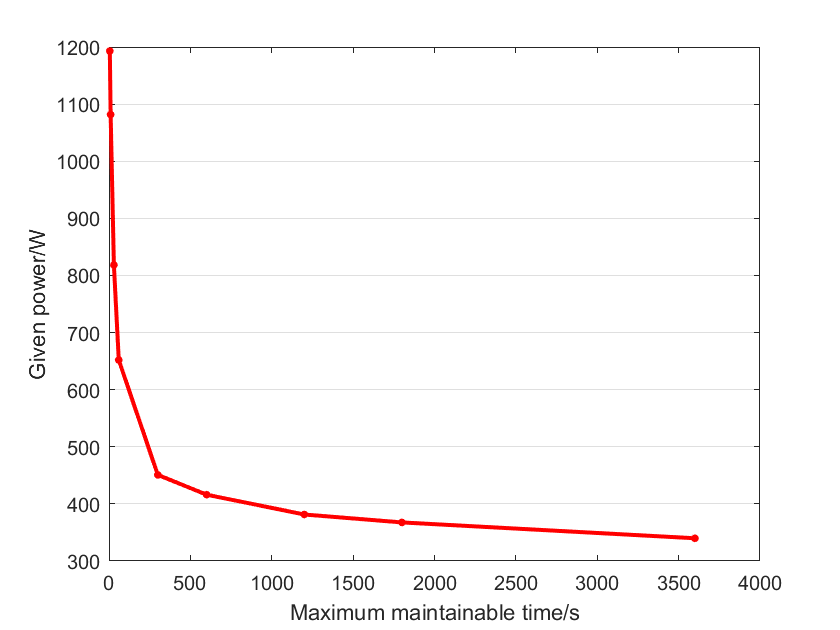

y2=polyval(p.z2,mmt.z2);
plot(mmt.z2,y2,'r','LineWidth',2);hold on% 换一种拟合
scatter(mmt.z2,gp.z2,15,'r','filled');
xlabel('Maximum maintainable time/s');ylabel('Given power/W')
set(gca,'ygrid','on')% 显示y轴网格线

Wpm.p75 = [23.26 19.78 17.92 13.36 10.74 7.34 6.77 6.29 6.02 5.47 4.91 4.64 4.42];
% papo运动员:专门从事比赛的骑手，比赛包括许多短而陡的攀登或许多急剧的加速。
Wpm.p=Wpm.z1.*linspace(1.05,0.9,13);
wei.p=wei.z1*1.01;  % ?????????????????????????????????
gp.p=Wpm.p*wei.p;
1./(gp.p./gp.z1);
mmt.p=mmt.z1*1;
n = 9 ;hold on;

[p.p]=polyfit(mmt.p,gp.p,n);

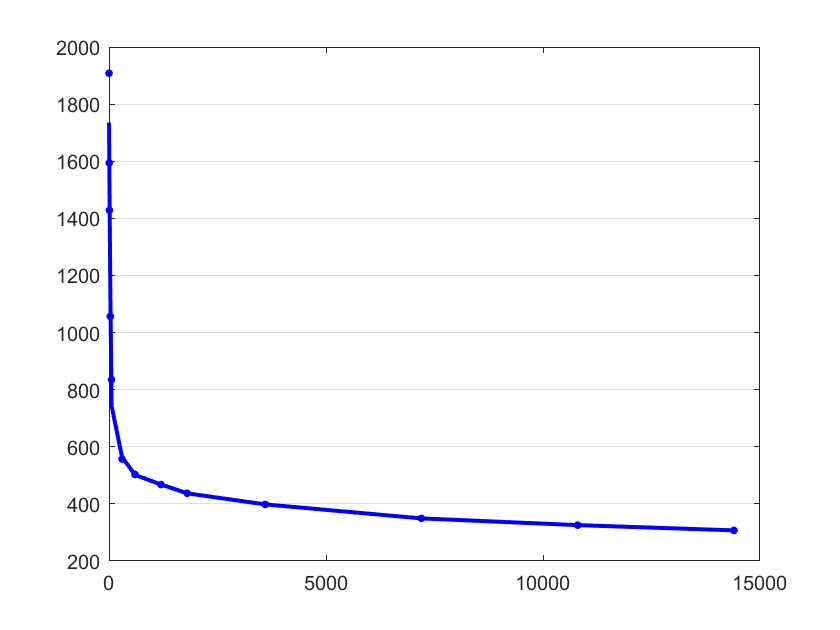

y.p=polyval(p.p,mmt.p);
figure
xlabel('Maximum maintainable time/s');ylabel('Given power/W')
plot(mmt.p,y.p,'b','LineWidth',2);hold on
scatter(mmt.p,gp.p,15,'b','filled');
set(gca,'ygrid','on')   % 显示y轴网格线
% 攀登者:专门从事多次长距离攀登比赛的骑手。
Wpm.c=Wpm.z1.*linspace(0.90,1.05,13);
wei.c=wei.z1*1.01;  % ?????????????????????????????????
gp.c=Wpm.c*wei.c;
1./(gp.c./gp.z1);
mmt.c=mmt.z1*1;
n = 9 ;hold on;

[p.c]=polyfit(mmt.c,gp.c,n);

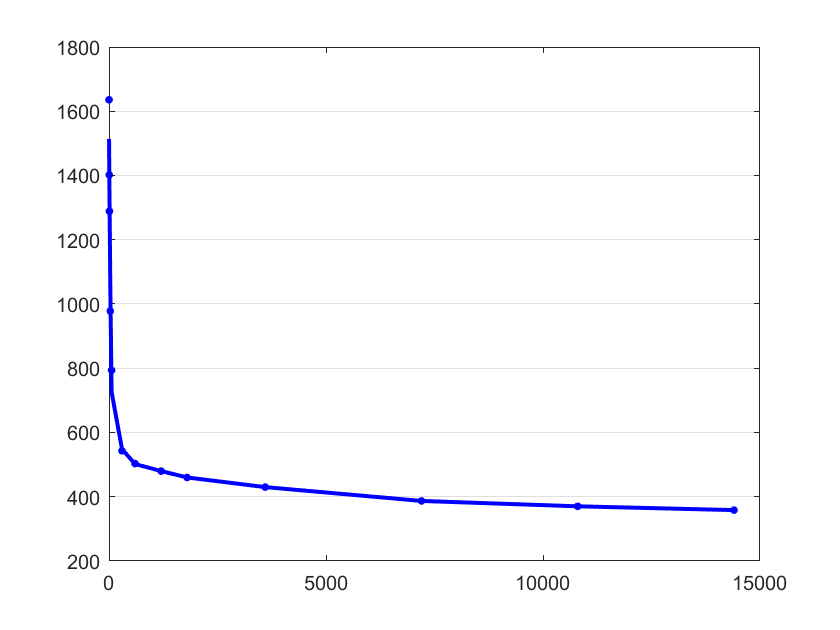

y.c=polyval(p.c,mmt.c);
figure
xlabel('Maximum maintainable time/s');ylabel('Given power/W')
plot(mmt.c,y.c,'b','LineWidth',2);hold on
scatter(mmt.c,gp.c,15,'b','filled');
set(gca,'ygrid','on')   % 显示y轴网格线

% 鲁勒尔:多面手，能在各种地形的比赛中表现出色。
% Rouleur: a rider that is a generalist and can do well in races with a wide variety of terrains.

% 短跑运动员
% 专门在短时间内产生极高力量的骑手。
% 这些骑手通常专注于在比赛结束时或中间冲刺阶段(如果比赛有中间冲刺阶段)获胜。
gp.q=[12.08 8.08;10.21 6.52];
wei.q=[72.64;mean([69 75])];
mmt.q=[30 120];
% 职业环法选手(前几名的，世界顶尖水平）骑自行车，每赛段160公里，平均输出功率在6W/kg左右，
% 再假设选手体重65kg，390W的平均输出功率已经是国际顶尖水平。不过冲刺爆发应该有1700+

## 2 参数设定

% 特定的
% 选手
m1=73;
Sw=0.5;

% 环境
% 不变
m0=6.8;
m=m1+m0;
g=9.8;
cr=0.004;   k.f = cr;   r1=cr;
cw=0.0397;  k.a = cw;   r2=cw;  % 空阻
% 可变 
mode=2;
switch mode
    case 1
        % rho=1.293*(实际压力 / 标准物理大气压)*(273.15 / 实际绝对温度);
    case 2
        rho = 1.29 % biaokuang changwen 1.2 05; 
end

rho = 1.2900

C=cw;S_tb=Sw;
kk=1/2*C*rho*S_tb;
% 地图

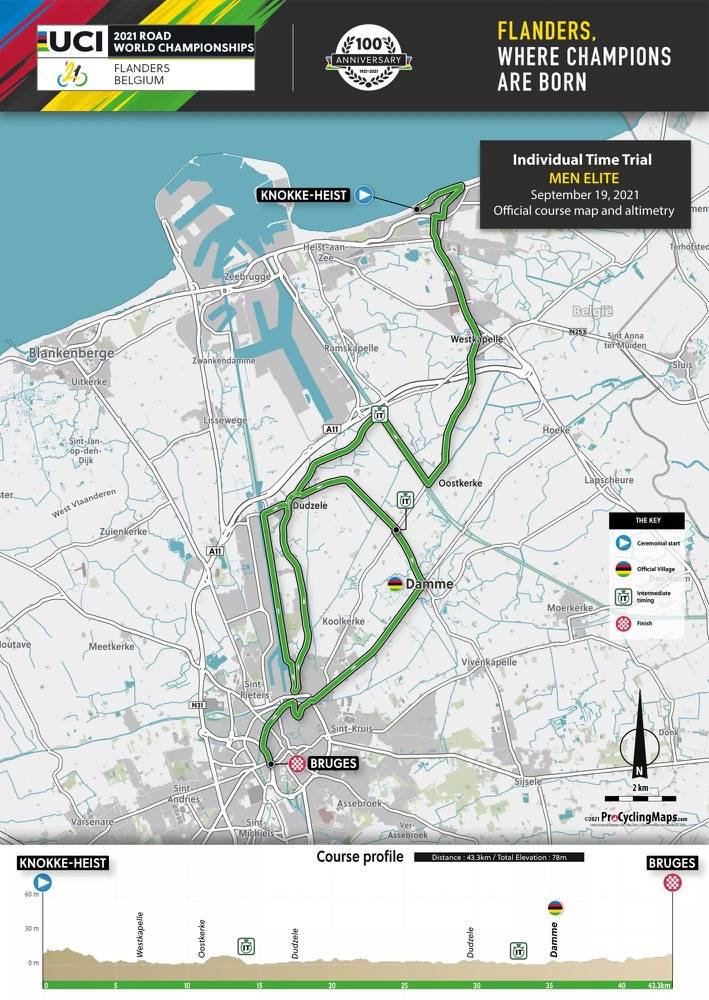

sx=[4 12 12.5 13.5 14 43.3]*1000;
ss.y=[-10 0 7 0 -7 0];
syms thetas
n=size(sx,2);
ss.x=sx-[0,sx(1:n-1)];
for i=1:size(sx,2)
    eqn1=sin(thetas)==ss.y(i)./ss.x(i)/1000;
    thetaa(i)=min(double(solve(eqn1,thetas)));
end
direction=deg2rad([80 195 270 180 0 180]);
L=[ss.x
    thetaa
    zeros(1,n)
    direction];
% S0=43.3;% 世界锦标赛个人计时赛男子组

treal=35*60+54+0.10/60;
va=max(sx)/treal;
va(2)=va*3.6;
% a = 1527.76798192966
% b = -11.3905587815884
% c = -0.427379679216585
% d = 0.00857557380788609
% X = treal;
% Y = a + b*X + c*X^2 + d*X^3;

Ppred=440;%polyval(p.z1,treal*1.1)

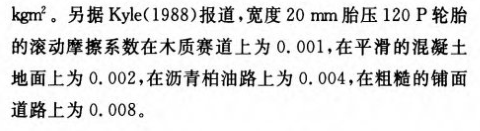

f = k.f*m*g;
% time
t1.a=0;  t1.b=5/10;  t1.c=60*60*2;
% test

Pmode = 0 ;
switch Pmode
    case 0
        P0 = 0.4*Ppred;
    case 1 % 直接输入
        P0 = 73*4;  % W
    case 2
        P0 = polyval(p.z1,t1.c);
    case 3
        P0 = 0.7*polyval(p.z1,t1.c);
end


## test

v0 = 0.1;
td=0;clear v theta S
for t=t1.a:t1.b:t1.c    % s
    td=td+1;
    if td==1
        I(td)=1;
    else z=S(td-1)./L(1,:);
        z1=max(find(z<1));
        if isempty(z1)==0
            I(td)=z1;
        else I(td)=size(L,2);
        end
    end
    theta(td)=L(2,I(td));
    plan = 11;
    switch plan
        case 11
            if td==1
                syms un
                v(td)=double(solve(m*un^2-(0.1*m-f*t)*un-P0*t==0,un>0));% fuhaojie
                Fw(td)=0;
            else switch L(3,I(td))
                case 0

t1 = 包含以下字段的 struct :
      a: 0
      b: 0.5000
      c: 7200
    end: 2140


                    Fw(td)=1/2*r2*rho*Sw*v(td-1)^2;
                    v(td)=((P0/v(td-1) - Fw(td))/m - (r1*cos(theta(td))+sin(theta(td)))*g) *t1.b + v(td-1);

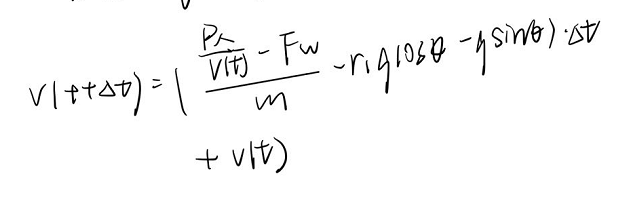

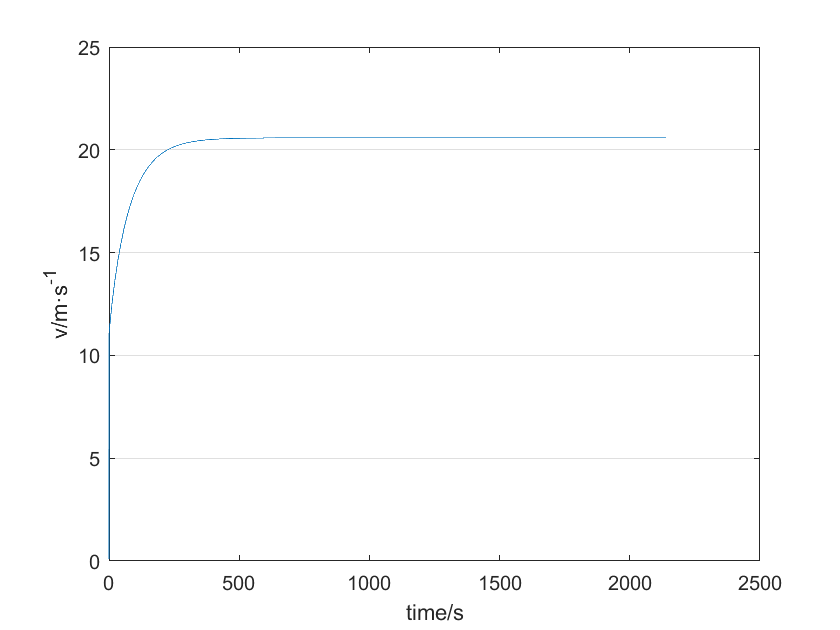

                otherwise warning('急转弯')

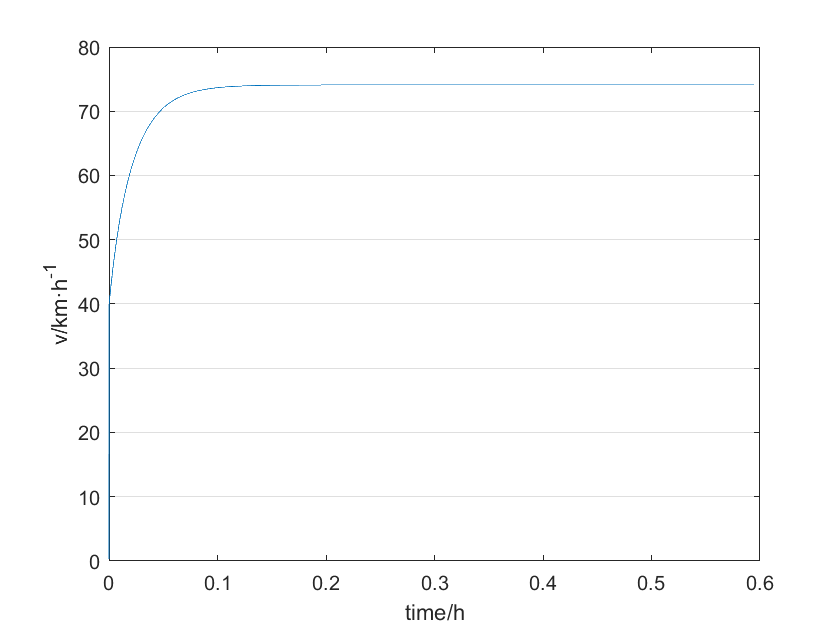

            end
            end


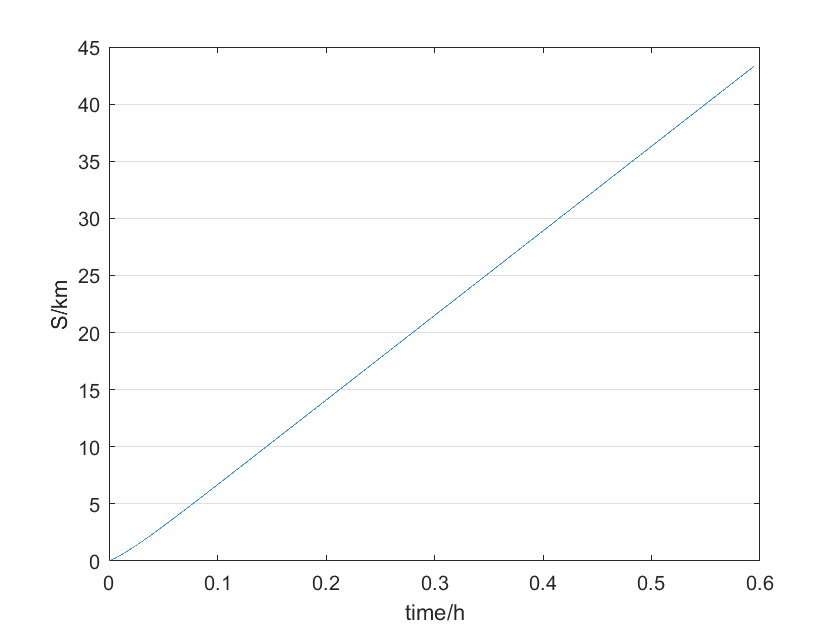

        case 1
            % syms un
            v(td)=max([1/20 - (5*((5531904*t^2)/9765625 + (149774208*t)/78125 + 2304/625)^(1/2))/192 - (49*t)/2500

                (5*((5531904*t^2)/9765625 + (149774208*t)/78125 + 2304/625)^(1/2))/192 - (49*t)/2500 + 1/20]);
            % v(td)=double(solve(m*un^2-(0.1*m-f*t)*un-P0*t==0,un>0));%fuhaojie
            % v(td)=((P0/v0-f)*td+v0)/m;
        case 2
            v(td)=P0/f*(1-exp(-1-f^2/(m*P0)*t));
        case 3
            syms un
            C = P0/f*log(P0/f);
            eqn = un+P0/f*log(abs(un-P0/f)) == -f/m*t+C;
            v(td) = double(vpasolve(eqn,un));
        otherwise warning('!')
    end
    if td==1;
        S(td)=1/2*(v0+v(td))*t1.b;
    else S(td) = S(td-1)+v(td)*t1.b;
        if S(td)>=sum(L(1,:))
            t1.end=t1.a+t1.b*(td-1)
            break
        end
    end
end
te=[t1.a:t1.b:t1.end];
figure;plot(te,v);hold on
xlabel('time/s');ylabel('v/m·s^{-1}');set(gca,'ygrid','on') ;hold off

figure;plot(te/3600,v*((1/1000)/(1/3600)));hold on
xlabel('time/h');ylabel('v/km·h^{-1}');set(gca,'ygrid','on') ;hold off

figure;plot(te/3600,S/1000);hold on
xlabel('time/h');ylabel('S/km');set(gca,'ygrid','on') ;hold off

figure;
[Y,H1,H2]=plotyy(te/60,v*((1/1000)/(1/3600)),te/60,S/1000);hold on
legend('v','S')
xlabel('time/min');
set(get(Y(1),'ylabel'),'string', 'v/km·h^{-1}');%,'fontsize',16
set(get(Y(2),'ylabel'),'string', 'S/km');
grid on;
pc=(t1.end-treal)/treal;

hold on;text(t1.end,sum(L(1,:)))
% S(t)=
% 环法自行车比赛平均时速为40公里每小时,下山时的时速会超过100公里每小时,在计时赛时可达70公里每小时<80

## 上下坡

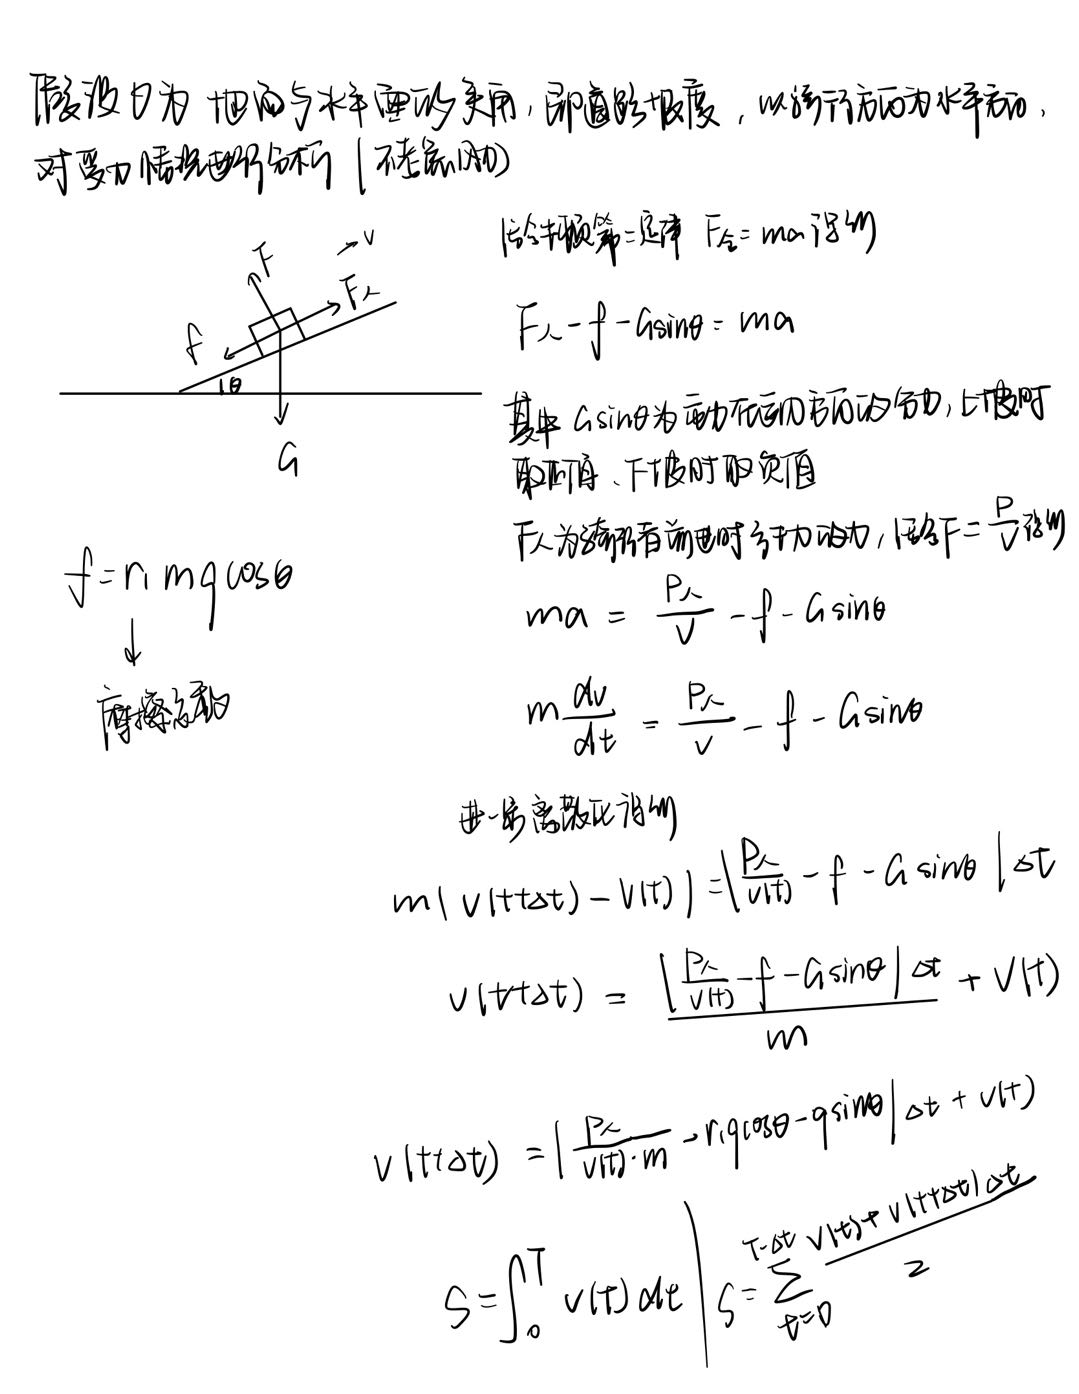

% theta=15;           % 坡度
% t1.a=0;  t1.b=10*2/10;  t1.c=60*60*4;
%
% dt = 1;
% for
%     f(t)=k.f*m*g*cos( deg2rad(theta));
%     v(t+dt )=abs(P/v(t)/m-k.f*g*cos(deg2rad(theta))-g*sin(deg2rad(theta)))*dt+v(t);
%     S(t)=sum(v(t)*dt );

## 验证

Emax=treal*440.5;
Etest=t1.end*440;
Etest/Emax

## 3

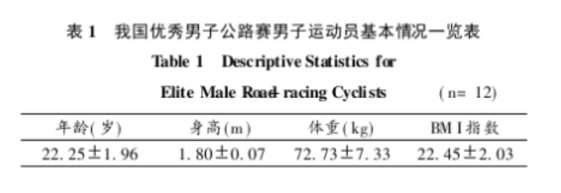

h = 1.80;     % rider